# Semantic Segmentation Using Deep Learning

## Load  Images

imgDir = fullfile('outImageFolder');
imds = imageDatastore(imgDir);

Display one of the images.

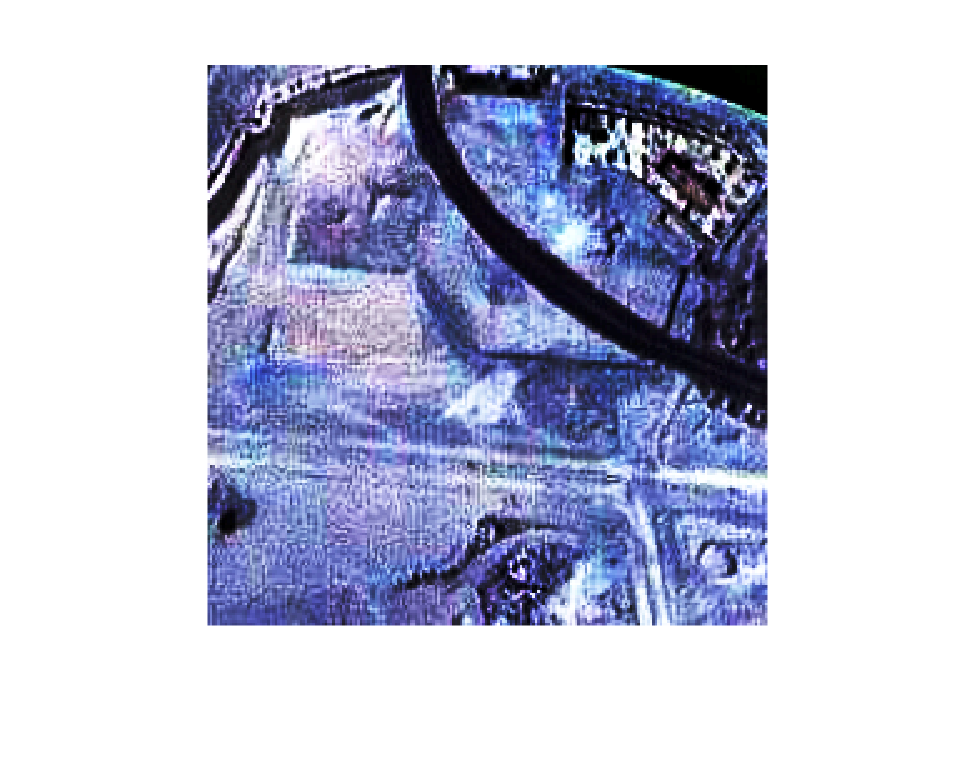

I = readimage(imds,59);
I = histeq(I);
imshow(I)

## Load Labeled Images

classes = [
    "Building"
    "Land_UnpavedArea"
    "Road"
    "Vegetation"
    "Water"
    "Unlabeled"
    ];

% Building: #3C1098
% Land (unpaved area): #8429F6
% Road: #6EC1E4
% Vegetation: #FEDD3A
% Water: #E2A929
% Unlabeled: #9B9B9B

labelIDs = camvidPixelLabelIDs();

Use the classes and label IDs to create the `pixelLabelDatastore.`

labelDir = fullfile('outMaskFolder');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

Read and display one of the pixel-labeled images by overlaying it on top of an image.

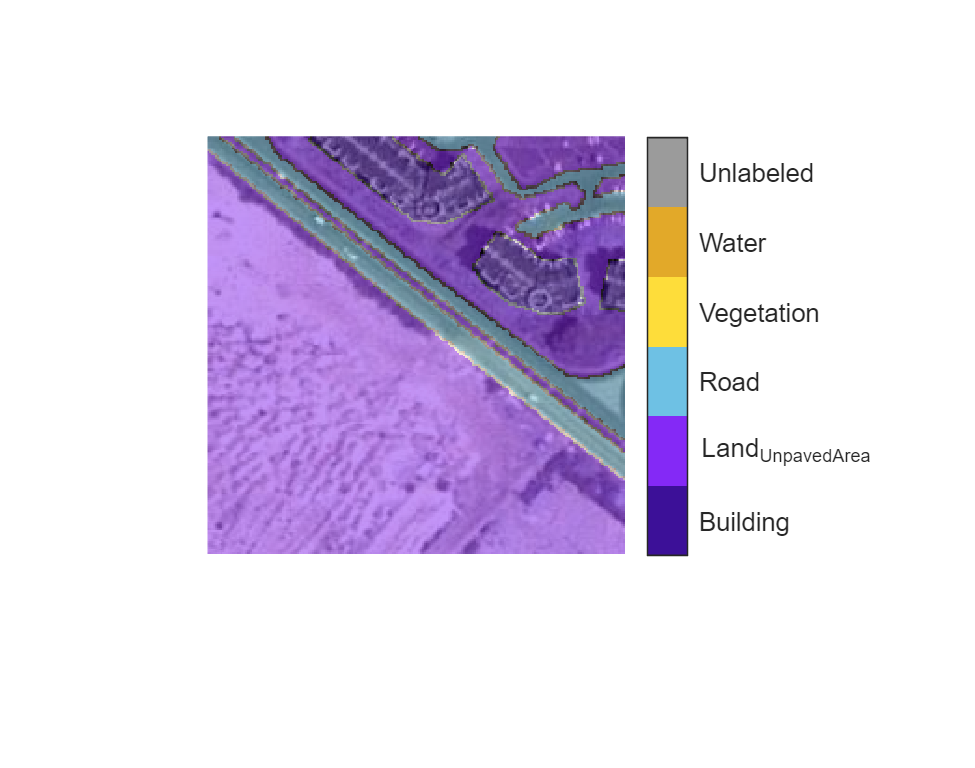

I = readimage(imds,110);
% I = histeq(I);
C = readimage(pxds,110);
cmap = camvidColorMap;
B = labeloverlay(I,C,'ColorMap',cmap,'Transparency',0.5);
imshow(B)
pixelLabelColorbar(cmap,classes);

## Analyze Dataset Statistics

To see the distribution of class labels in the CamVid dataset, use [countEachLabel](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7). 

This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 6×3 table
            Name            PixelCount    ImagePixelCount
    ____________________    __________    _______________

    {'Building'        }    3.5554e+06      1.8214e+07   
    {'Land_UnpavedArea'}    1.4646e+07      3.0156e+07   
    {'Road'            }    2.4321e+06      2.3834e+07   
    {'Vegetation'      }    3.0031e+06      1.7361e+07   
    {'Water'           }    6.7353e+06      2.0371e+07   
    {'Unlabeled'       }    2.7214e+05      7.7773e+06   


Visualize the pixel counts by class.

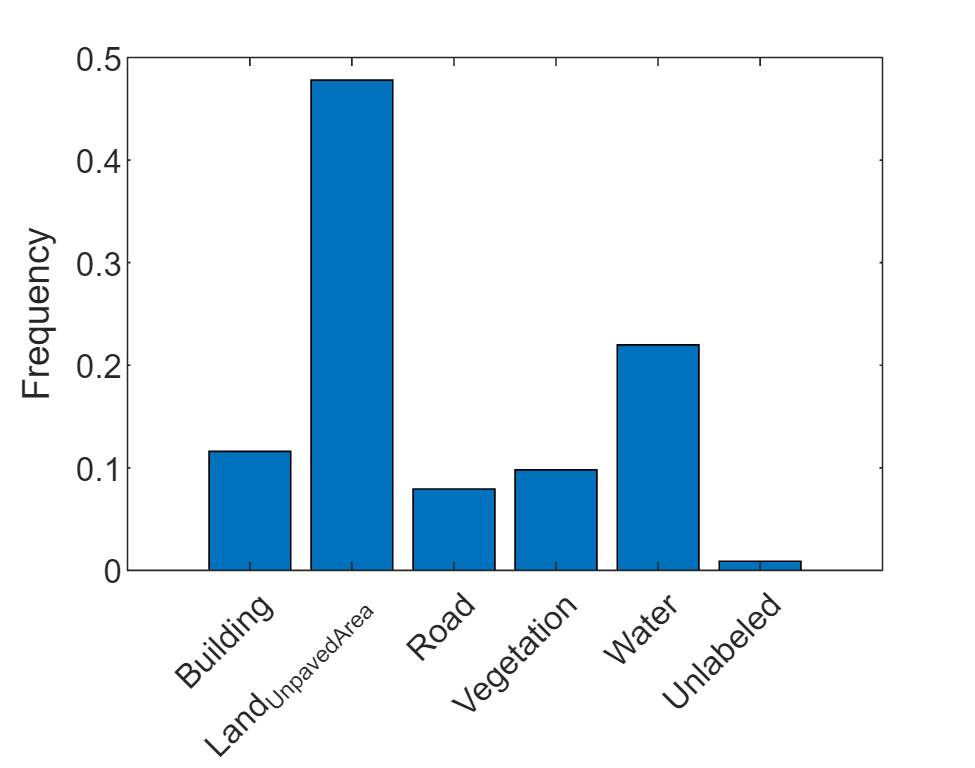

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

## Prepare Training, Validation, and Test Sets

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds);

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 389

numValImages = numel(imdsVal.Files)

numValImages = 130

numTestingImages = numel(imdsTest.Files)

numTestingImages = 129

## Create the Network

% Specify the network image size. This is typically the same as the traing image sizes.
imageSize = [224 224 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
resnet18;
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

## Balance Classes Using Class Weighting

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.9431
    0.3790
    1.8040
    1.0642
    0.5568
    5.2610


Specify the class weights using a [ `pixelClassificationLayer`](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

## Select Training Options

% Define validation data.
dsVal = combine(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

## Data Augmentation

dsTrain = combine(imdsTrain, pxdsTrain);
% xTrans = [-10 10];
% yTrans = [-10 10];
% dsTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

## Start Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:26 |       17.34% |       21.77% |       2.0482 |       2.0000 |          0.0010 |
|       1 |           2 |       00:00:30 |       26.50% |              |       1.9615 |              |          0.0010 |
|======================================================================================================================|
Training finished: Stopped manually.


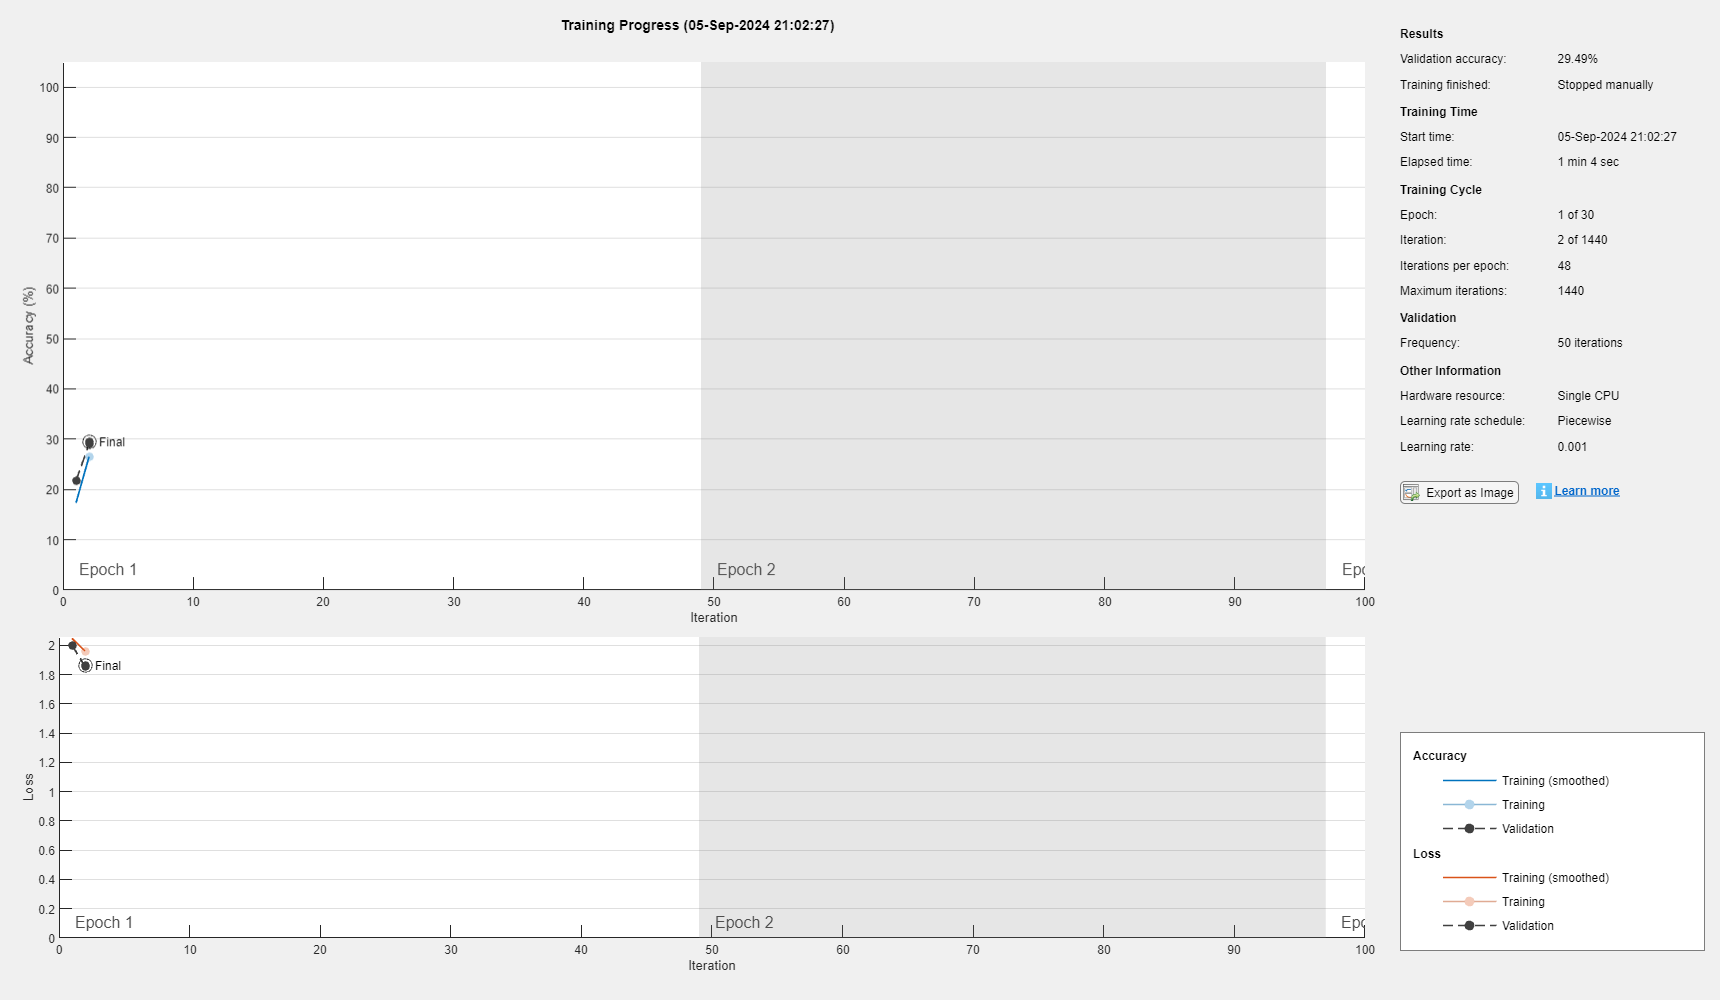

% doTraining = false;
% if doTraining    
    [net, info] = trainNetwork(dsTrain,lgraph,options);

% end

## Test Network on One Image

As a quick sanity check, run the trained network on one test image. 

I = readimage(imdsTest,35);
C = semanticseg(I, net);

Display the results.

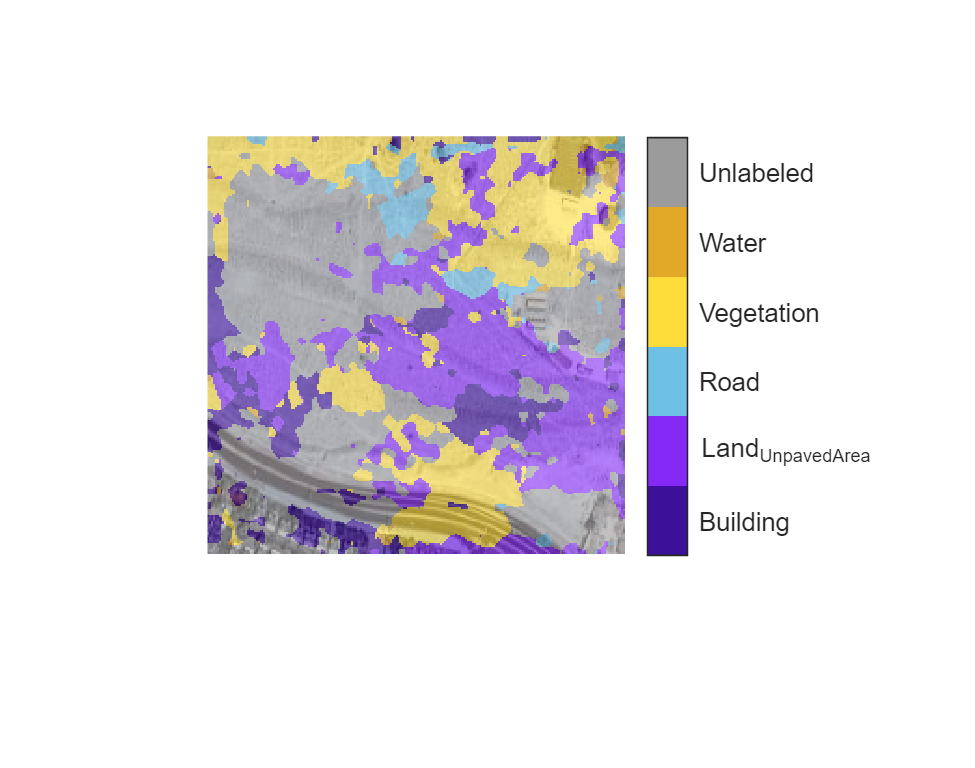

B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)
pixelLabelColorbar(cmap, classes);

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. 

The green and magenta regions highlight areas where the segmentation results differ from the expected ground truth.

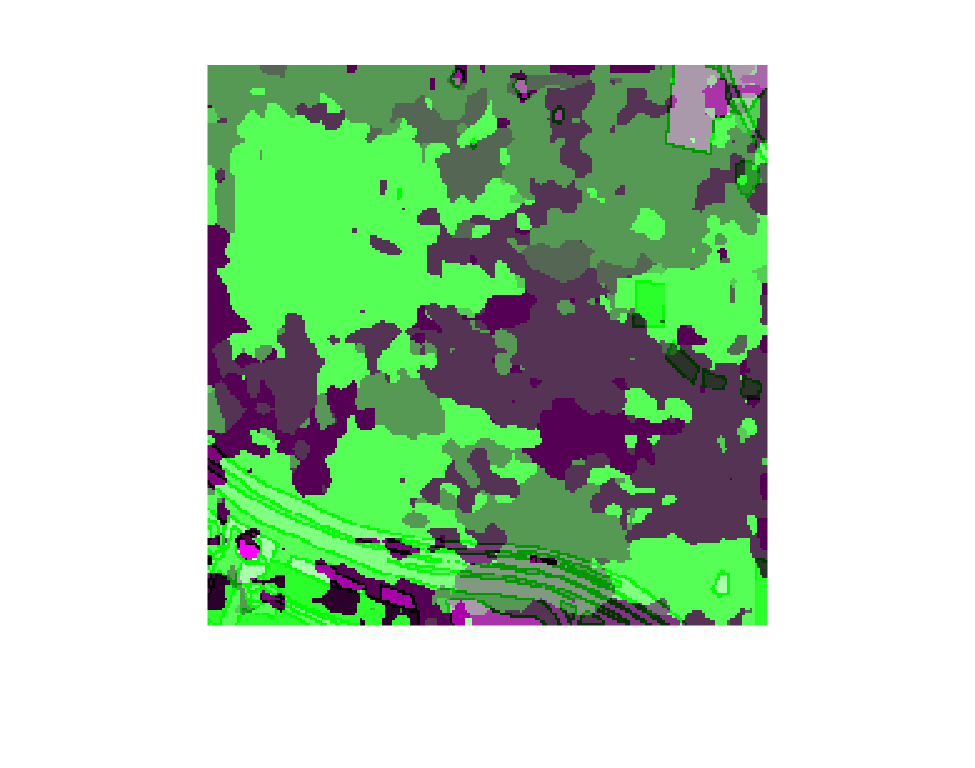

expectedResult = readimage(pxdsTest,35);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)

Use the  [`jaccard`](docid:images_ref.mw_fc8c8913-3141-4127-abf4-c7d90c72c870) function to measure IoU.

iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 6×2 table
         classes             iou    
    __________________    __________

    "Building"              0.051635
    "Land_UnpavedArea"       0.25151
    "Road"                 0.0078663
    "Vegetation"            0.047899
    "Water"                        0
    "Unlabeled"           0.00015937


The IoU metric confirms the visual results. 

 Other common segmentation metrics include the [Dice index](docid:images_ref#mw_1ee709d7-bf6b-4ac9-8f5d-e7caf72497d4) and the [Boundary-F1](docid:images_ref#mw_53845c75-154c-4cbe-99c2-54ef222fecd7) contour matching score.

## Evaluate Trained Network

To measure accuracy for multiple test images, run[ semanticseg](docid:vision_ref#mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) on the entire test set. A mini-batch size of 4 is used to reduce memory usage while segmenting images. You can increase or decrease this value based on the amount of GPU memory you have on your system. 

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

`semanticseg` returns the results for the test set as a `pixelLabelDatastore` object. The actual pixel label data for each test image in `imdsTest` is written to disk in the location specified by the `'WriteLocation'` parameter. Use [ `evaluateSemanticSegmentation`](docid:vision_ref.mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) to measure semantic segmentation metrics on the test set results. 

metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

`evaluateSemanticSegmentation` returns various metrics for the entire dataset, for individual classes, and for each test image. To see the dataset level metrics, inspect `metrics.DataSetMetrics` .

metrics.DataSetMetrics

The dataset metrics provide a high-level overview of the network performance. To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

metrics.ClassMetrics

## Supporting Functions

function labelIDs = camvidPixelLabelIDs()
labelIDs = { ...
    
    % "Building"
    [
    60 16 152; ... % "Building"
    ]
    
    % "Land (Unpaved Area)"
    [
    132 41 246; ... % "Land (Unpaved Area)"
    ]

    % "Road"
    [
    110 193 228; ... % "Road"
    ]
    
    % "Vegetation"
    [
    254 221 58; ... % "Vegetation"
    ]

    % "Water"
    [
    226 169 41; ... % "Water"
    ]
    
    % "Unlabeled"
    [
    155 155 155; ... % "Unlabeled"
    ]
    };
end

% Building: #3C1098
% Land (unpaved area): #8429F6
% Road: #6EC1E4
% Vegetation: #FEDD3A
% Water: #E2A929
% Unlabeled: #9B9B9B


function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end

function cmap = camvidColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
    60 16 152   % "Building"
    132 41 246  % "Land (Unpaved Area)"
    110 193 228 % "Road"
    254 221 58  % "Vegetation"
    226 169 41  % "Water"
    155 155 155 % "Unlabeled"
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end

function data = augmentImageAndLabel(data, xTrans, yTrans)
% Augment images and pixel label images using random reflection and
% translation.

for i = 1:size(data,1)
    
    tform = randomAffine2d(...
        'XReflection',true,...
        'XTranslation', xTrans, ...
        'YTranslation', yTrans);
    
    % Center the view at the center of image in the output space while
    % allowing translation to move the output image out of view.
    rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
    
    % Warp the image and pixel labels using the same transform.
    data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
    data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
    
end
end